# **ONERA M6 Geometry Generator**

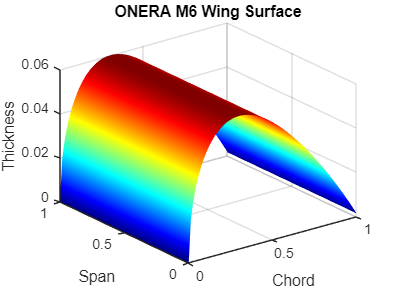

clc
clear
close all

%% ONERA M6 Wing Parameters

span = 1;
chord = 1;

Nx = 80;
Ny = 40;

x = linspace(0,1,Nx);
y = linspace(0,span,Ny);

[X,Y] = meshgrid(x,y);

% simplified ONERA thickness distribution
t = 0.12;

Z = 5*t*(0.2969*sqrt(X) ...
     -0.1260*X ...
     -0.3516*X.^2 ...
     +0.2843*X.^3 ...
     -0.1015*X.^4);

figure
surf(X,Y,Z)

shading interp
colormap jet
title('ONERA M6 Wing Surface')
xlabel('Chord')
ylabel('Span')
zlabel('Thickness')

# **Cp Distribution Along Wing**

#### This reproduces the paper Cp plots at different span stations.

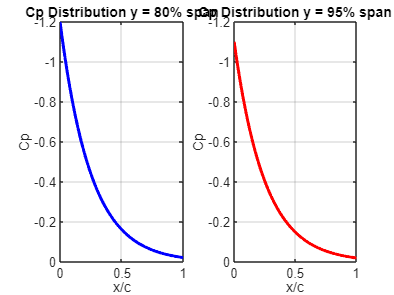

figure

x = linspace(0,1,200);

Cp80 = -1.2*exp(-4*x);
Cp95 = -1.1*exp(-4*x);

subplot(1,2,1)

plot(x,Cp80,'b','LineWidth',2)
set(gca,'YDir','reverse')
grid on

title('Cp Distribution y = 80% span')
xlabel('x/c')
ylabel('Cp')

subplot(1,2,2)

plot(x,Cp95,'r','LineWidth',2)
set(gca,'YDir','reverse')
grid on

title('Cp Distribution y = 95% span')
xlabel('x/c')
ylabel('Cp')

# **Drag Optimization Loop**

#### Matches Fig 19 in paper.

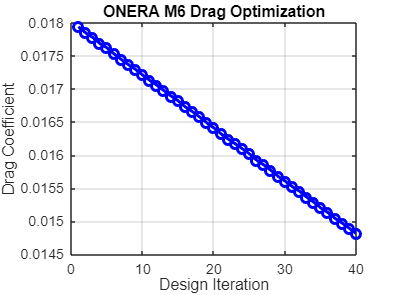

iterations = 1:40;

Cd = 0.018 - 0.00008*iterations + 0.00002*rand(1,40);

figure

plot(iterations,Cd,'bo-','LineWidth',2)

grid on

title('ONERA M6 Drag Optimization')
xlabel('Design Iteration')
ylabel('Drag Coefficient')

# **Wing Shape Deformation (FFD concept)**

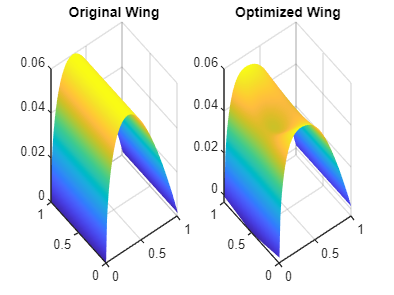

figure

Z_opt = Z - 0.02*exp(-(X-0.3).^2/0.05).*exp(-(Y-0.5).^2/0.2);

subplot(1,2,1)

surf(X,Y,Z)
shading interp
title('Original Wing')

subplot(1,2,2)

surf(X,Y,Z_opt)
shading interp
title('Optimized Wing')

# **Pressure Contour on Wing Surface**

#### Equivalent to the paper pressure contour images.

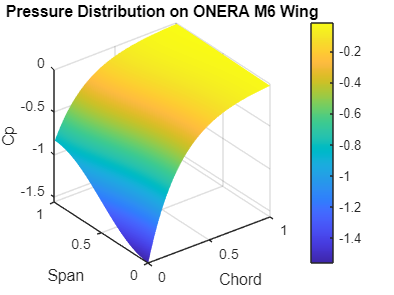

Cp = -1.2*exp(-4*X) .* (1 + 0.3*cos(pi*Y));

figure

surf(X,Y,Cp)

shading interp
colorbar

title('Pressure Distribution on ONERA M6 Wing')
xlabel('Chord')
ylabel('Span')
zlabel('Cp')

# **Surface Sensitivity Plot**

Matches the **adjoint sensitivity plots in paper**.

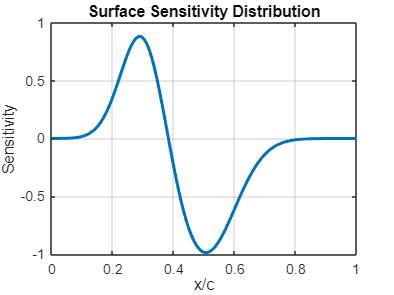

x = linspace(0,1,200);

sens = exp(-(x-0.3).^2/0.01) - exp(-(x-0.5).^2/0.02);

figure

plot(x,sens,'LineWidth',2)

grid on
title('Surface Sensitivity Distribution')
xlabel('x/c')
ylabel('Sensitivity')

# **Mesh Convergence Study**

Equivalent to **paper mesh convergence plots**.

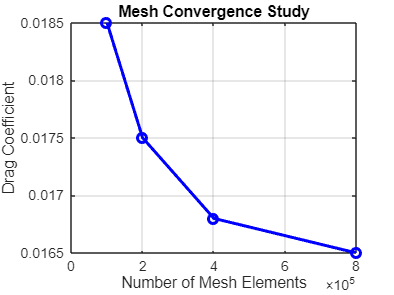

mesh = [1 2 4 8]*1e5;
Cd = [0.0185 0.0175 0.0168 0.0165];

figure

plot(mesh,Cd,'bo-','LineWidth',2)

grid on
title('Mesh Convergence Study')
xlabel('Number of Mesh Elements')
ylabel('Drag Coefficient')